# EECS 965 Homework 15                                 William Powers 2025

#### ***a. Say that sensor ***$A$* returns a measurement of: *$\mathbf{x}_A=[-8.0, \ 53.0]^T$*. Using only this measurement vector, determine the MMSE estimate of *$\theta$* along with the estimate error covariance matrix.*

Being that the relationship between the measurement $\mathbf{x}$ and source $\mathbf{\theta}$ is linear and both the measurement and source are stated to be Gaussian random variables, we can restricted the search for finding the MMSE estimate to the class of linear estimators of the form 

$\hat{\mathbf{\theta}}_{MMSE} = \mathbf{Ax}$. 

It has been shown in Steven Kay's *Fundamentals of Statistical Signal Processing: Detection Theory* that the optimal estimate in this form with respect to mean squared error is

$\mathbf{A}_{MMSE} = \mathbf{C}_{\theta, x} \mathbf{C}^{-1}_{x,x}$      where      $\mathbf{C}_{\theta, x} = \mathbb{E}_{x, \theta} \{ \mathbf{\theta}\mathbf{x}^T \}$      and     $\mathbf{C}_{x, x} = \mathbb{E}_{x, \theta} \{ \mathbf{x}\mathbf{x}^T \}$.

From this, we see that obtaining the optimal linear MMSE estimate requires knowledge of the joint PDF $p(\mathbf{\theta, x})$ which is used in both of the above expectations. Expanding out each of the above expectations yeilds


$$\mathbf{C}_{\theta, x} = \mathbb{E}_{\theta, x} \{ \mathbf{\theta}\mathbf{x}^T \} \ \rightarrow \ \mathbf{x} = \mathbf{H}\mathbf{\theta} + \mathbf{w} \ \rightarrow \ 
\mathbb{E}_{\theta, x} \{ \mathbf{\theta}\mathbf{x}^T \} = \mathbb{E}_{\theta} \{ \mathbf{\theta \theta H}^T \} + \mathbb{E}_{x, \theta} \{ \mathbf{\theta}\mathbf{w}^T\}
= \mathbf{C}_{\theta}\mathbf{H}^T$$



$$\mathbf{C}_{x, x} = \mathbb{E}_{\theta, x} \{ \mathbf{x}\mathbf{x}^T \} \ \rightarrow \ \mathbf{x} = \mathbf{H}\mathbf{\theta} + \mathbf{w} \ \rightarrow \ 
\mathbb{E}_{\theta, x} \{ \mathbf{x}\mathbf{x}^T \} = \mathbb{E}_{\theta} \{ \mathbf{H\theta \theta H}^T \} + \mathbb{E} \{ \mathbf{w}\mathbf{w}^T\} = 
\mathbf{HC}_{\theta}\mathbf{H}^T + \mathbf{C}_w$$


which, given that the system, covariance, and measurement matrices are known, can be used to solve for the linear MMSE estimate.


$$\mathbf{C}_{\theta} = 

\left[
\begin{array}{cc}
10 & 0 \\
0 & 10
\end{array}
\right]


$$
      
$$\mathbf{C}_{w, A} = 

\left[
\begin{array}{cc}
4 & 0 \\
0 & 4
\end{array}
\right]


$$
      
$$\mathbf{H}_{A} = 

\left[
\begin{array}{cc}
10 & 10 \\
10 & -20
\end{array}
\right]


$$
      
$$\mathbf{x}_{A} = 

\left[
\begin{array}{cc}
-8.0 & 53.0
\end{array}
\right]^T


$$


% define given system and measurement parameters
C_theta = [10 0; 0 10];
C_wA = [4 0; 0 4];
H_A = [10 10; 10 -20];
x_A = [-8 53]';

% solve for MMSE estimate
A = (C_theta * H_A')*inv(H_A*C_theta*H_A' + C_wA);
theta_a1 = A * (x_A);
disp(theta_a1);

    1.2315
   -2.0321




$$\hat{\mathbf{\theta}}_{MMSE, A} =

\left[
\begin{array}{cc}
1.2315 & -2.0321
\end{array}
\right]^T


$$


Defining the resulting estimation error as $\mathbf{\epsilon} = \mathbf{\theta} - \hat{\mathbf{\theta}}_{MMSE} = \mathbf{\theta} - \mathbf{C}_{\theta, x} \mathbf{C}_{x, x}^{-1} \mathbf{x}$, the corresponding error covariance matrix is likewise defined as


$$\mathbf{C}_{\epsilon} = \mathbb{E}_{\theta, x} \{ \mathbf{\epsilon} \mathbf{\epsilon}^T \}
= \mathbf{C}_{\theta} - \mathbf{C}_{\theta, x} \mathbf{C}_{x, x}^{-1} \mathbf{C}_{\theta, x}^T$$


which after plugging in the previously defined definitions of each covariance matrix and further simplifiying yeilds

$\mathbf{C}_{\epsilon} = \left( \mathbf{H}^T \mathbf{C}_w^{-1}\mathbf{H} + \mathbf{C}_{\theta}^{-1} \right)^{-1}$.

% solve for MMSE estimate error covariance
C_e_a1 = inv(H_A'*inv(C_wA)*H_A + inv(C_theta));
disp(C_e_a1);

    0.0222    0.0044
    0.0044    0.0089




$$\mathbf{C}_{\epsilon} = 

\left[
\begin{array}{cc}
0.0222 & 0.0044 \\
0.0044 & 0.0089
\end{array}
\right]


$$


#### ***b. Say that sensor ***$B$* returns a measurement of: *$\mathbf{x}_B=[-27.0, \ 24.0, \ 28.0]^T$*. Using only this measurement vector, determine the MMSE estimate of *$\theta$* along with the estimate error covariance matrix.*

Following the theory built in *Part a*, again the model stated in the problem is a linear combination of measurement $\mathbf{x}$ and source $\mathbf{\theta}$ with both vectors jointly Gaussian. Becuase of these two conditions, the linear MMSE estimate can be reused plugging in the newly given noise covariance, measurement, and system matrices.


$$\mathbf{C}_{\theta} = 

\left[
\begin{array}{cc}
10 & 0 \\
0 & 10
\end{array}
\right]


$$
      
$$\mathbf{C}_{w, B} = 

\left[
\begin{array}{cc}
9 & 0 & 0 \\
0 & 9 & 0 \\
0 & 0 & 9
\end{array}
\right]


$$
      
$$\mathbf{H}_{B} = 

\left[
\begin{array}{cc}
10 & 20 \\
20 & 0 \\
10 & -10
\end{array}
\right]


$$
      
$$\mathbf{x}_{B} = 

\left[
\begin{array}{cc}
-27.0 & 24.0 & 28.0
\end{array}
\right]^T


$$


% define given system and measurement parameters
C_theta = [10 0; 0 10];
C_wB = [9 0 0; 0 9 0; 0 0 9];
H_B = [10 20; 20 0; 10 -10];
x_B = [-27 24 28]';

% solve for MMSE estimate
A = (C_theta * H_B')*inv(H_B*C_theta*H_B' + C_wB);
theta_b1 = A * (x_B);
disp(theta_b1);

    1.1253
   -1.8617




$$\hat{\mathbf{\theta}}_{MMSE, B} =

\left[
\begin{array}{cc}
1.1253 & -1.8617
\end{array}
\right]^T


$$


Again, defining the estimate error as $\mathbf{\epsilon} = \mathbf{\theta} - \hat{\mathbf{\theta}}_{MMSE} = \mathbf{\theta} - \mathbf{C}_{\theta, x} \mathbf{C}_{x, x}^{-1} \mathbf{x}$, the error covariance matrix is formed using the equation derived in *Part a*.

% solve for MMSE estimate error covariance
C_e_b1 = inv(H_B'*inv(C_wB)*H_B + inv(C_theta));
disp(C_e_b1);

    0.0155   -0.0031
   -0.0031    0.0186




$$\mathbf{C}_{\epsilon} = 

\left[
\begin{array}{cc}
0.0155 & -0.0031 \\
-0.0031 & 0.0186
\end{array}
\right]


$$


#### ***c. Now, use the measurement vector ***$\mathbf{x}_B=[-27.0, \ 24.0, \ 28.0]^T$* to update the estimate and error covariance of part a (do not explicitly use vector *$\mathbf{x}_A$* in your calculations).*

The information provided by sensor $B$ can be directly included into the estimation of source $\mathbf{\theta}$ by sensor $A$ as it introduces additional measurement samples containing additional information than was avaliable in *Part a *alone. From this theory, if this additional information is not redudant to the original measurement, the result should further resolve the estimate and provide a smaller (volumetrically) error covariance.

In *Part a*, a linear MMSE estimate was derived and can be equivalently viewed as the a posteriori expectation of source $\mathbf{\theta}$ as well as the error covariance matrix being the a posteriori covariance.


$$\hat{\mathbf{\theta}}_{MMSE} = \mathbf{\mu}_{\theta | x_A}$$
      
$$\mathbf{C}_{\epsilon} = \mathbf{C}_{\theta | x_A}$$


These statistical moments completely describe the information obtained from measurement $\mathbf{x}_A$ and are likewise used as the starting point of the next estimate using measurement $\mathbf{x}_B$. Following this intuition, the linear MMSE estimate using measurement vector $\mathbf{x}_B$ is found using the definition from *Part a *albeit now the a priori information is the a posteriori statistics derived from the first measurement.


$$\hat{\mathbf{\theta}}_{MMSE,A \rightarrow B} = \mathbf{A}(\mathbf{x} - \mu_{\theta|x_A})$$
   
$$\rightarrow$$
   
$$\mathbf{A} = \mathbf{C}_{\theta, x} \mathbf{C}^{-1}_{x,x}$$
   
$$\rightarrow$$
   
$$\mathbf{C}_{\theta, x} = \mathbf{C}_{\theta|x_A}\mathbf{H}^T$$
   
$$\rightarrow$$
   
$$\mathbf{C}_{x, x} = \mathbf{H
C}_{\theta|x_A}\mathbf{H}^T + \mathbf{C}_w$$



$$\mathbf{C}_{\theta|x_A} = 

\left[
\begin{array}{cc}
0.0222 & 0.0044 \\
0.0044 & 0.0089
\end{array}
\right]


$$
      
$$\mathbf{C}_{w, B} = 

\left[
\begin{array}{cc}
9 & 0 & 0 \\
0 & 9 & 0 \\
0 & 0 & 9
\end{array}
\right]


$$
      
$$\mathbf{H}_{B} = 

\left[
\begin{array}{cc}
10 & 20 \\
20 & 0 \\
10 & -10
\end{array}
\right]


$$
      
$$\mathbf{x}_{B} = 

\left[
\begin{array}{cc}
-27.0 & 24.0 & 28.0
\end{array}
\right]^T


$$
      
$$\mathbf{\mu}_{\theta|x_A} =

\left[
\begin{array}{cc}
1.2315 & -2.0321 & 0
\end{array}
\right]^T
$$


% define a priori information of theta from A
C_theta_A = [0.0222 0.0044; 0.0044 0.0089];
mu_theta_A = [1.2315 -2.0321]';

% redefine system matrix and measurement from B
C_wB = [9 0 0; 0 9 0; 0 0 9];
H_B = [10 20; 20 0; 10 -10];
x_B = [-27 24 28]';

% compute updated MMSE estimate using a priori from A
A = (C_theta_A * H_B')*inv(H_B*C_theta_A*H_B' + C_wB);
theta_a2 = mu_theta_A + A * (x_B - H_B*mu_theta_A);
disp(theta_a2);

    1.1929
   -1.9900




$$\hat{\mathbf{\theta}}_{MMSE, A \rightarrow B} =

\left[
\begin{array}{cc}
0.4371 & -0.4881
\end{array}
\right]^T


$$


Similarly, the covariance computation utilizes the a posteriori statistics obtained from the original estimation of $\mathbf{\theta}$.

% solve for MMSE estimate error covariance
C_e_a2 = inv(H_B'*inv(C_wB)*H_B + inv(C_theta));
disp(C_e_a2);

    0.0155   -0.0031
   -0.0031    0.0186




$$\mathbf{C}_{\epsilon} = 

\left[
\begin{array}{cc}
0.0087 & 0.0007 \\
0.0007 & 0.0056
\end{array}
\right]


$$


#### ***d. Now, use the measurement vector ***$\mathbf{x}_A=[-8.0 \ 53.0]^T$* to update the estimate and error covariance of part b (do not explicitly use vector *$\mathbf{x}_B$* in your calculations).*

Following the logic built in *Part c, * here the estimated statistics of source $\mathbf{\theta}}$ obtained through sensor $B$ are used as the a priori information in further resolving the estimate made by sensor $A$. Specifically, the updated linear estimate is defined as


$$\hat{\mathbf{\theta}}_{MMSE,B \rightarrow A} = \mathbf{A}(\mathbf{x} - \mu_{\theta|x_B})$$
   
$$\rightarrow$$
   
$$\mathbf{A} = \mathbf{C}_{\theta, x} \mathbf{C}^{-1}_{x,x}$$
   
$$\rightarrow$$
   
$$\mathbf{C}_{\theta, x} = \mathbf{C}_{\theta|x_B}\mathbf{H}^T$$
   
$$\rightarrow$$
   
$$\mathbf{C}_{x, x} = \mathbf{H
C}_{\theta|x_B}\mathbf{H}^T + \mathbf{C}_w$$


with a priori statistics, the measurement vector, and system matrix defined below.


$$\mathbf{C}_{\theta|x_B} = 

\left[
\begin{array}{cc}
0.0155 & -0.0031 \\
-0.0031 & 0.0186
\end{array}
\right]



$$
      
$$\mathbf{C}_{w, A} = 

\left[
\begin{array}{cc}
4 & 0 \\
0 & 4
\end{array}
\right]


$$
      
$$\mathbf{H}_{A} = 

\left[
\begin{array}{cc}
10 & 10 \\
10 & -20
\end{array}
\right]


$$
      
$$\mathbf{x}_{A} = 

\left[
\begin{array}{cc}
-8.0 & 53.0
\end{array}
\right]^T


$$
      
$$\mathbf{\mu}_{\theta|x_B} =

\left[
\begin{array}{cc}
1.1253 & -1.8617
\end{array}
\right]^T$$


% define a priori information of theta from B
C_theta_B = [0.0155 -0.0031; -0.0031 0.0186];
mu_theta_B = [1.1253 -1.8617]';

% define given system and measurement parameters
C_wA = [4 0; 0 4];
H_A = [10 10; 10 -20];
x_A = [-8 53]';

% solve for MMSE estimate
A = (C_theta_B * H_A')*inv(H_A*C_theta_B*H_A' + C_wA);
theta_b2 = mu_theta_B + A * (x_A - H_A*mu_theta_B);
disp(theta_b2);

    1.1930
   -1.9902




$$\hat{\mathbf{\theta}}_{MMSE, B \rightarrow A} =

\left[
\begin{array}{cc}
0.7911 & -1.5643
\end{array}
\right]^T


$$


With corresponding covariance matrix computed below also using the a priori definitions obtained from the initial measurement using sensor $B$.

% solve for MMSE estimate error covariance
C_e_b2 = inv(H_A'*inv(C_wA)*H_A + inv(C_theta));
disp(C_e_b2);

    0.0222    0.0044
    0.0044    0.0089




$$\mathbf{C}_{\epsilon} = 

\left[
\begin{array}{cc}
0.0087 & 0.0007 \\
0.0007 & 0.0056
\end{array}
\right]


$$


#### *e. Compare the result of part c and part d. Provide profound thoughts.*

The incorporation of a priori information from sensor $B$ into the estimation of source $\mathbf{\theta}$ by sensor $A$ is is visually quantized below in the error ellipsoid plot where the ellipsoid boundaries extend one standard deviation. The error ellipsoids shown around each measurement are directly proportional to the estimates resulting error covariance matrice, becuase of this, we can examine the geometry of the 'no priori' and 'a priori' cases to better understand the update. It is clear that the uncertainty in the direction of $\theta_1$ was decreased while the uncertainty in direction $\theta_2$ was increased. Volumetrically, these ellipsoids appear to be relatively equal and therefore we can state that the additional information provided by sensor $B$ did not improve the estimators preformance.

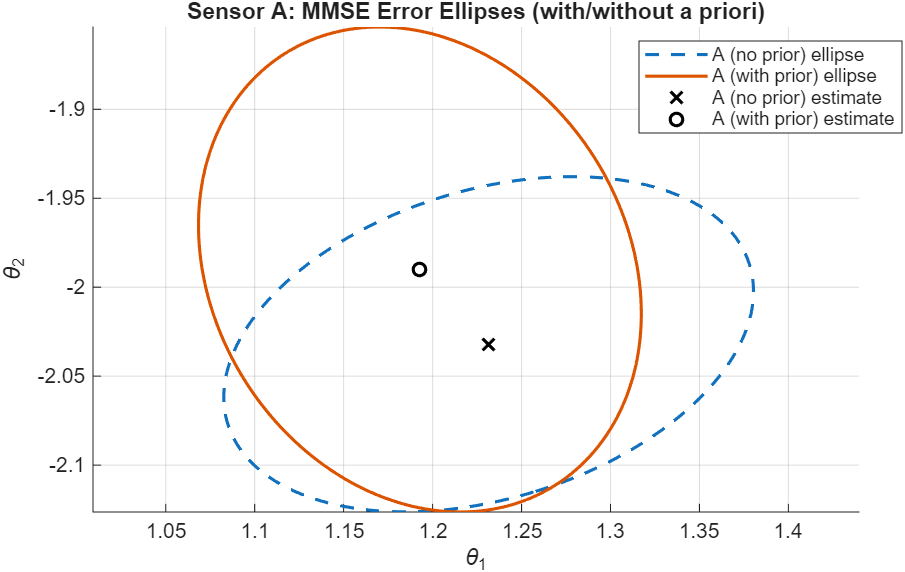

Inclusion of information from sensor $A$ into the estimate of source $\mathbf{\theta}$ by source $B$ likewise provided similar results. Again, an error ellipsoid plot is shown below in which here the uncertainty in direction $\theta_1$ was increased while the uncertainty in direction $\theta_2$ was decreased. The volume of the ellipsoid utilizing the a priori information here however is slightly smaller indicating that this additional information does improve the estimator preformance.

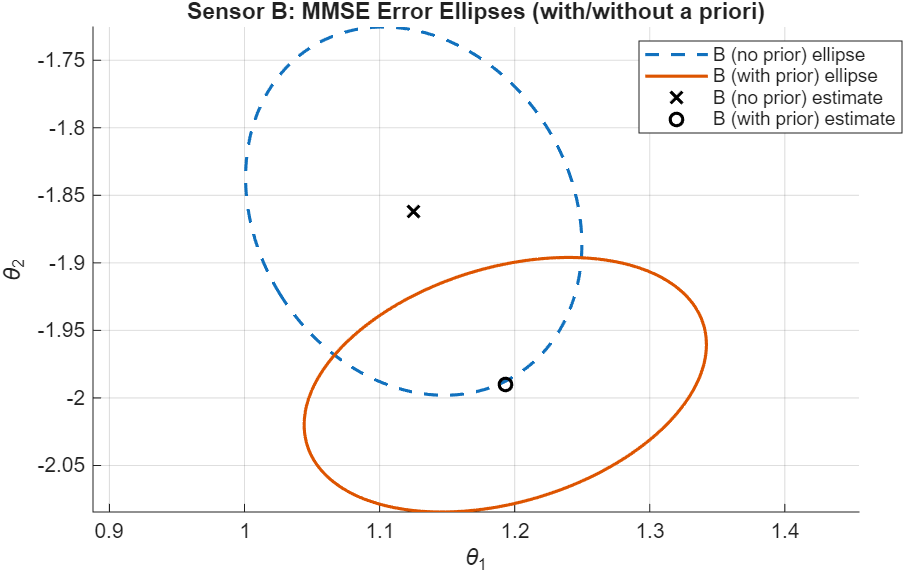

%% ------------- Plot for Sensor A --------------------------

k = 1;
[x_a1, y_a1] = errorEllipse(theta_a1, C_e_a1, k);
[x_a2, y_a2] = errorEllipse(theta_a2, C_e_a2, k);

figure('Name','Error Ellipses - Sensor A');
hold on; grid on; axis equal;

% Ellipses
plot(x_a1, y_a1, '--', 'LineWidth', 1.5, 'DisplayName','A (no prior) ellipse');
plot(x_a2, y_a2, '-',  'LineWidth', 1.5, 'DisplayName','A (with prior) ellipse');

% Point estimates
plot(theta_a1(1), theta_a1(2), 'kx', 'MarkerSize', 8, 'LineWidth', 1.5, ...
    'DisplayName','A (no prior) estimate');
plot(theta_a2(1), theta_a2(2), 'ko', 'MarkerSize', 6, 'LineWidth', 1.5, ...
    'DisplayName','A (with prior) estimate');

xlabel('\theta_1');
ylabel('\theta_2');
title('Sensor A: MMSE Error Ellipses (with/without a priori)');
legend('Location','best');
hold off;


%% ------------- Plot for Sensor B --------------------------
[x_b1, y_b1] = errorEllipse(theta_b1, C_e_b1, k);
[x_b2, y_b2] = errorEllipse(theta_b2, C_e_b2, k);

figure('Name','Error Ellipses - Sensor B');
hold on; grid on; axis equal;

% Ellipses
plot(x_b1, y_b1, '--', 'LineWidth', 1.5, 'DisplayName','B (no prior) ellipse');
plot(x_b2, y_b2, '-',  'LineWidth', 1.5, 'DisplayName','B (with prior) ellipse');

% Point estimates
plot(theta_b1(1), theta_b1(2), 'kx', 'MarkerSize', 8, 'LineWidth', 1.5, ...
    'DisplayName','B (no prior) estimate');
plot(theta_b2(1), theta_b2(2), 'ko', 'MarkerSize', 6, 'LineWidth', 1.5, ...
    'DisplayName','B (with prior) estimate');

xlabel('\theta_1');
ylabel('\theta_2');
title('Sensor B: MMSE Error Ellipses (with/without a priori)');
legend('Location','best');
hold off;

function [x_ell, y_ell] = errorEllipse(theta, C, k)
    if nargin < 3
        k = 1;
    end
    t = linspace(0, 2*pi, 200);
    circle = [cos(t); sin(t)];
    [V, D] = eig(C);
    D = max(D, 0);
    A = V * sqrt(D);
    ell = k * A * circle + theta(:);
    x_ell = ell(1, :);
    y_ell = ell(2, :);
end
